# Gene Expression Project

## Goals: 

- Segment images of bacteria (first for one image)

- Measure the mean fluorescence (first for one image)

- Do all of this for all of the images for each bacterial strain

- Calculate the fold change in gene expression from these data

- Fit the binding energies of the three operators (binding sites) using non-linear least squares regression

## Segmenting the images

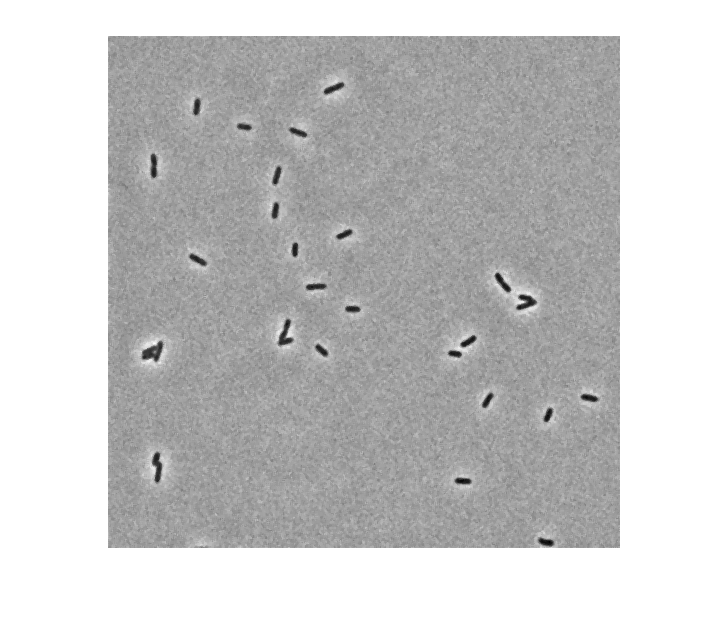

% Open the phase contrast image in the BacteriaSampleImages folder
Phase = imread('BacteriaSampleImages/phase.tif');
% Take a look at it
imshow(Phase,[])


% Normalise this image to a greyscale image (using the mat2gray function)
Phase = mat2gray(Phase);
imshow(Phase)

Thesholding the image to find the bacteria

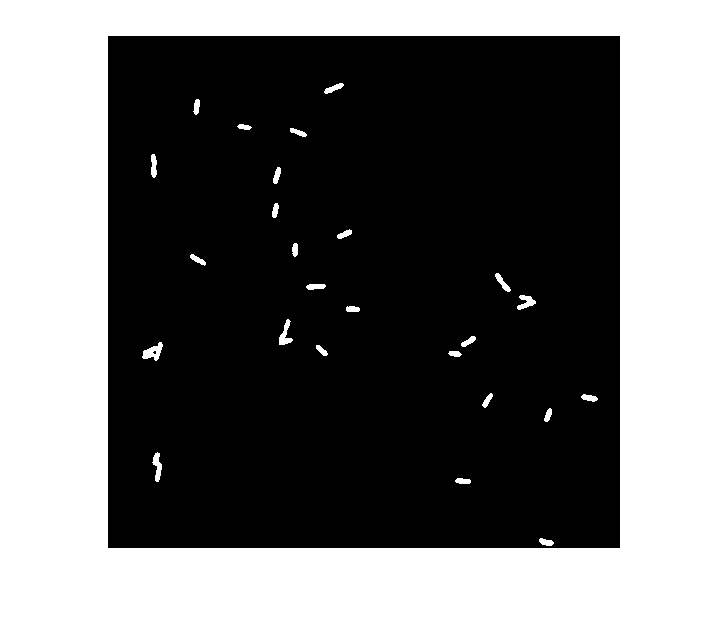

% We want to threshold the image, so let's take a look at the values of the pixels in the bacteria
% and the background

% Let's try applying a threshold 
Threshold = 0.4;
ImThresh = Phase <Threshold;
% And now let's take a look at the resulting image
imshow(ImThresh)

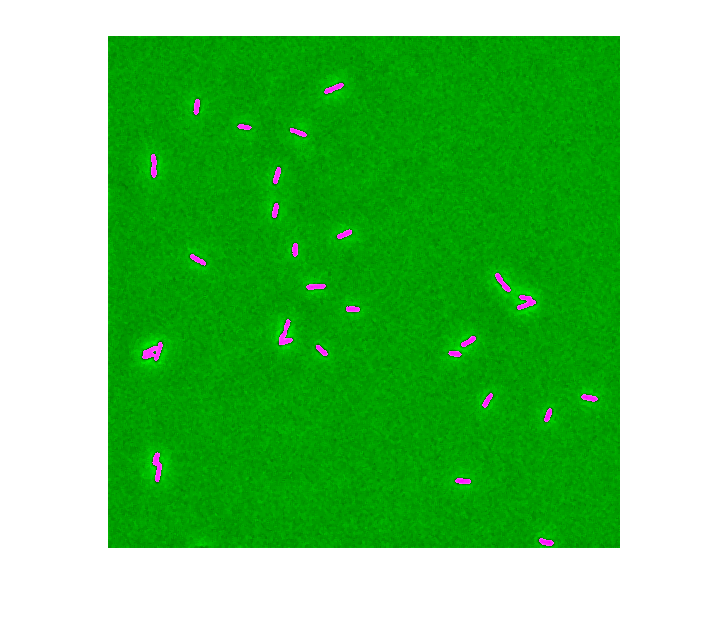

% How well did we do? We can look at this using the cool function imshowpair (let's look at what
% inputs this function needs using help)
imshowpair(Phase, ImThresh)

Finding individual objects so that we can filter out aggregates etc.

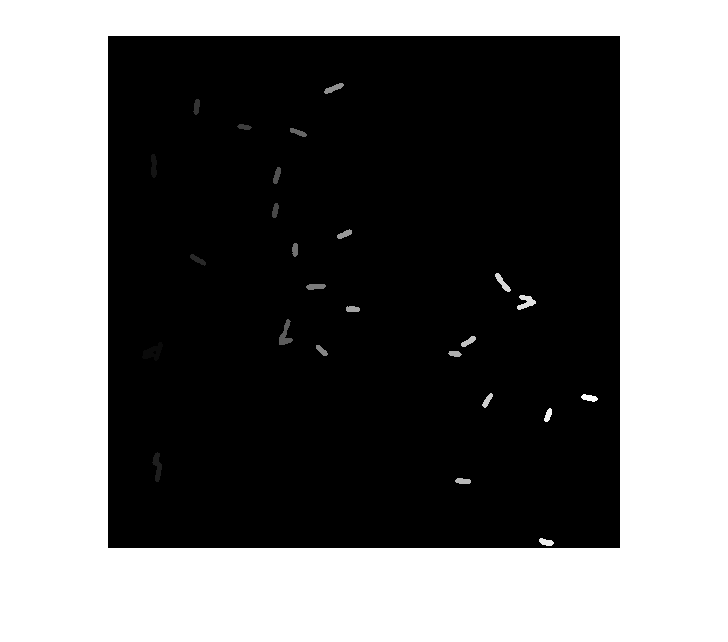

% Label the objects in the image
ImLabel = bwlabel(ImThresh);
imshow(ImLabel,[])


% Let's take a look at the labelled image

% using bwlabel'd image to pull out an individual object
a = [1,2,3,5,1,2,3,4,5,6]

a =      1     2     3     5     1     2     3     4     5     6


a==2

ans = 1×10 logical array
   0   1   0   0   0   1   0   0   0   0


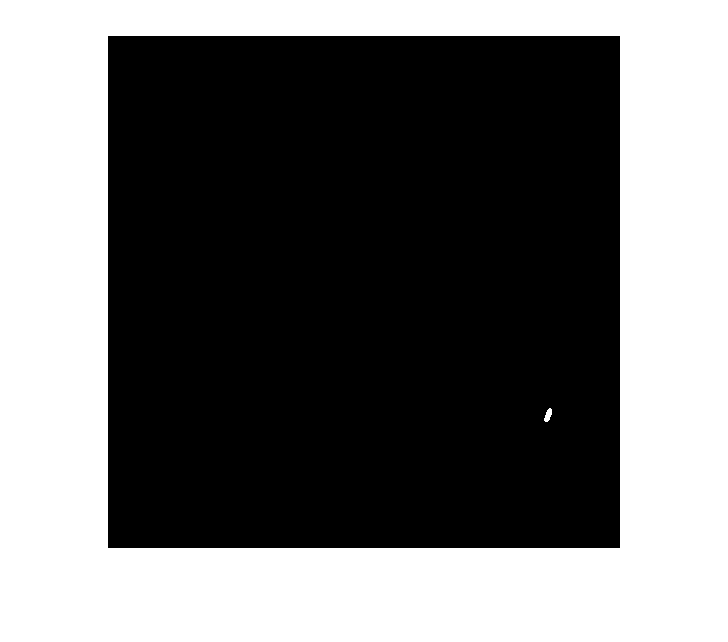


imshow(ImLabel==24)


% Find the properties of the bactira now that we can identify them individuallu
Properties = regionprops(ImLabel, 'Area')

Properties = 25×1 struct array with fields:
    Area


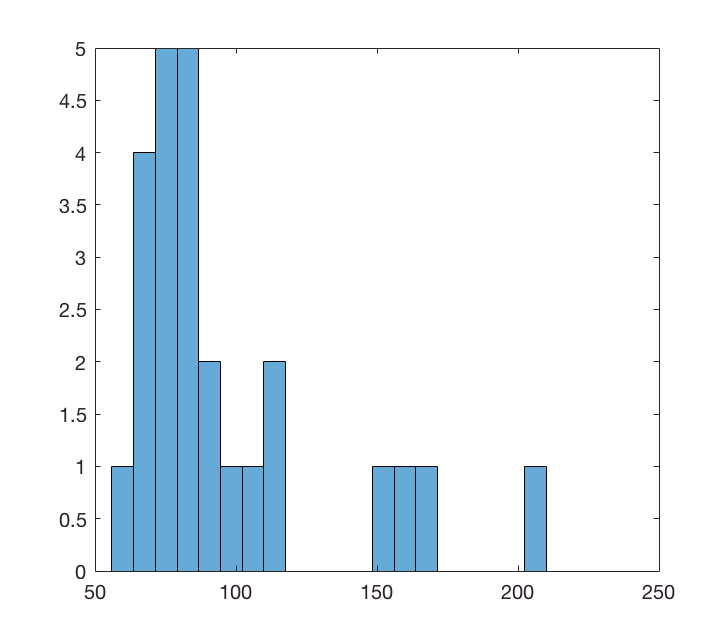

Properties(24).Area;

Areas = [Properties.Area];
histogram(Areas,20)

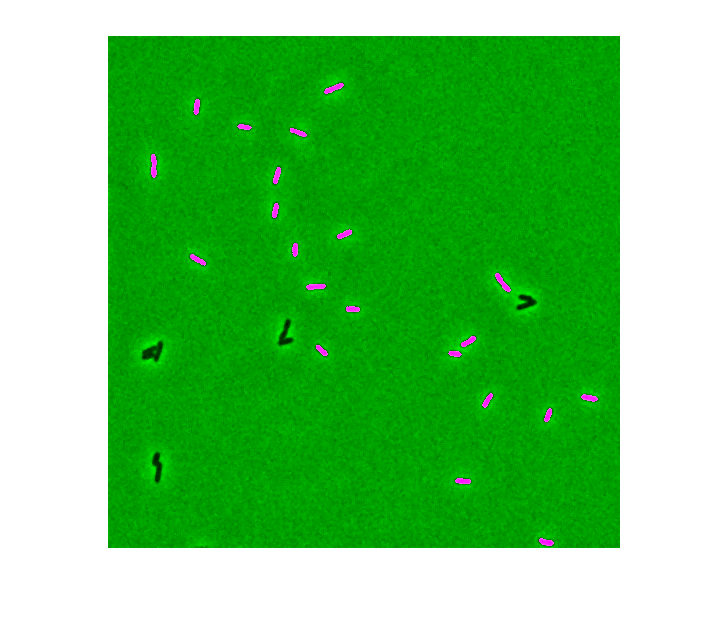


%Let's get rid of everything with an area > 125 on the basis of the histogram
MaxArea = 125;

%create a blank image
ImNew  =  zeros(size(Phase));

% Now let's grab the good bacteria and put them in it
for i = 1:length(Properties)
    if Areas(i) < MaxArea
        ImNew = (ImNew + (ImLabel==i)); 
    end
end

imshowpair(Phase, ImNew)

## Measuring fluorescence of bacterial cells

We're first going to do this for one sample image, before putting together everything that we've done thus far into a full script to analyse our actual dataset

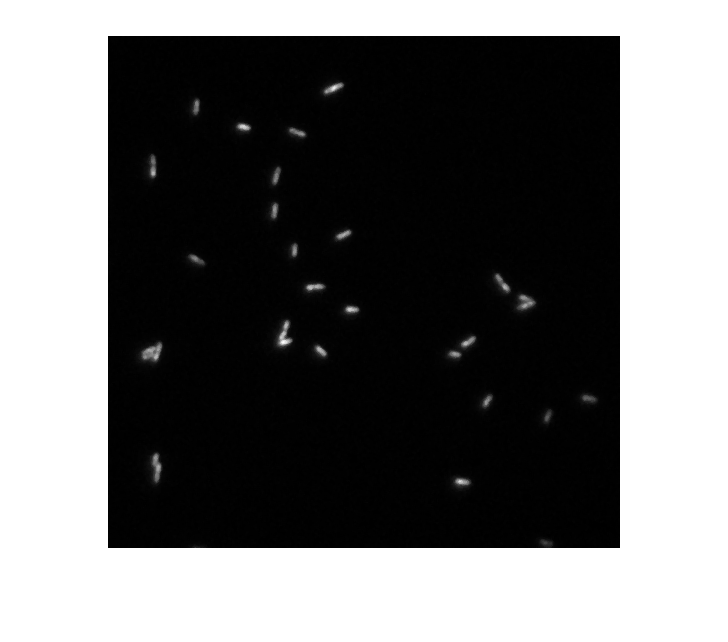

% Open sample fluorescence image
Fluo = imread('BacteriaSampleImages/fluorescence.tif');

% Take a look at it
imshow(Fluo, [])

To extract the fluorescence for each bacterium, we will use the mask that we made above (from the phase contrast image) and multiply it with this fluorescence image

% Re-label the objects in the filtered mask image
ImFilt = bwlabel(ImNew);

Now as an example, let's pull out the pixels from the fluorescence image belonging to bacterium #10. We're going to do this using the command immultiply

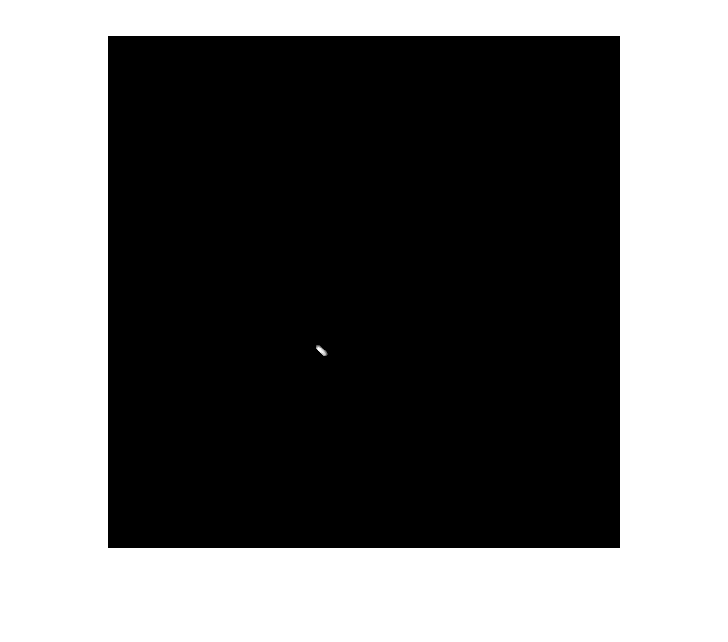

% Extract fluorescence for cell #10. 
FluoFilter = immultiply(Fluo, ImFilt ==10);    %use immultiply to make easier in matlab so it doesn't fuss
imshow(FluoFilter,[])

sum(sum(FluoFilter))

ans = 191154

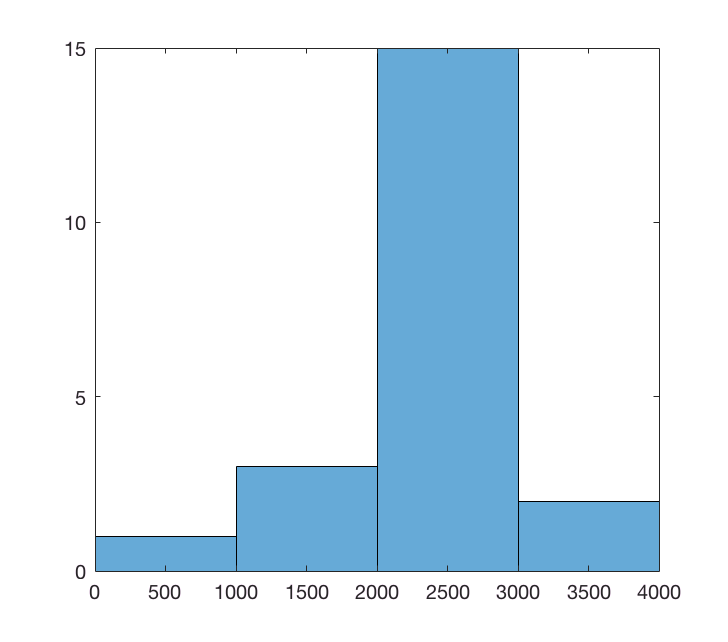


% Fluorescene per pixel
sum(sum(FluoFilter))/sum(sum(ImFilt==10));

% For loop to ask the fluorescence in each cell object in ImFilt
% for i = 1:max(max(ImFilt))
%    CellFluo(i) = sum(sum(immultiply(Fluo, ImFilt ==i)));
%    PixelFluo(i) = CellFluo(i)/sum(sum(ImFilt==i));
% end
% 
% histogram(PixelFluo)
% title('histogram fluorence per pixel single image')
% mean(PixelFluo)


% We can also do this in a different way so that we can add ALL of the pixel fluorescences for each bacteria
% across all the images for a given bacterial strain - this will help us later on
PixelFluo = [];
for i = 1:max(max(ImFilt))
    PixelFluo = [PixelFluo, sum(sum(immultiply(Fluo, ImFilt ==i)))...
        /sum(sum(ImFilt==i))];
end

histogram(PixelFluo)

## Analyse ALL of the images for a single bacterial strain

First, get the images in the data folder.

% Get the list of images in the data folder for the strain of interest (in this example, Operator 1, Repressor # = 0)
DPhase=dir('O1_R22_phase_pos_*.tif');
DFluo=dir('O1_R22_yfp_pos_*.tif');

% Initialise array into which to save the fluorescence values (NOTE: this will be fluorescence per pixel)
PixelFluo = [];

% Define min and max area for area filtering 
MaxArea = 125;
MinArea = 30;

% Loop through each image file to analyse it (there are 20 images per bacterial strain)
for i=2%:length(DPhase)
    
    %Load the phase image
    Phase=imread(DPhase(i).name);
    
    %Normalize the phase image
    Phase = mat2gray(Phase);
    
    %Load the fluorescence image
    Fluo = imread(DFluo(i).name);
    
    %Define the threshold to use for the Phase image (we found this above)
    Threshold = 0.4;
    
    %Threshold the image
    ImThresh = Phase < Threshold;
    
    %Label the regions
    ImLabel = bwlabel(ImThresh);
    
    %Get their areas
    Properties = regionprops(ImLabel,'Area');
    Areas = [Properties.Area];
    
    %Filter by area
    ImNew = zeros(size(Phase));         %create a blank image
    for j = 1:length(Areas)
        if Areas(j)>MinArea
            if Areas(j)<MaxArea
                ImNew = ImNew + (ImLabel==j);
            end
        end
    end
    
    %Relabel the image
    ImFilter = bwlabel(ImNew);
    
    %Find the fluorescence in each cell
    for j = 1:max(max(ImFilter))
        % Find the total fluorescence in the cell object
        CellFluo = sum(sum(immultiply(Fluo,ImFilter==j)));
        
        % Find the area of the cell object
        Area = sum(sum(ImFilter==j));
        
        % Calculate the fluorescence intensity per pixel for this cell object and save it in the vector PixelFluo
        PixelFluo = [PixelFluo, CellFluo/Area];
    end
    
end

% Find the mean pixel fluorescence for the bacterial strain of interest to report to the board!
mean(PixelFluo)
